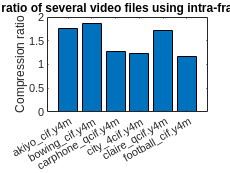

%lossless intra 
clear;

akiyo_original = 45621044;
bowing_original = 45621044;
carphone_original = 14524448;
city_original = 364957238;
claire_original = 18782912;
football_original = 39538238;

akiyo_intra = 25877633;
bowing_intra = 24548951;
carphone_intra = 11424982;
city_intra = 297149278;
claire_intra = 10886252;
football_intra = 34043817;

akiyo_time = [3.373 2.736];
bowing_time = [3.064 2.682];
carphone_time = [1.157 1.022];
city_time = [28.086 20.396];
claire_time = [1.350 1.219];
football_time = [3.057 1.910];

akiyo_frames = 300;
bowing_frames = 300;
carphone_frames = 382;
city_frames = 600;
claire_frames = 494;
football_frames = 260;

X = categorical({'akiyo\_cif.y4m','bowing\_cif.y4m','carphone\_qcif.y4m','city\_4cif.y4m', 'claire\_qcif.y4m', 'football\_cif.y4m'});
Y = [(akiyo_original / akiyo_intra) (bowing_original/bowing_intra) (carphone_original/carphone_intra) (city_original/city_intra) (claire_original/claire_intra) (football_original/football_intra)];
bar(X, Y);
title("Compression ratio of several video files using intra-frame encoding only");
ylabel("Compression ratio");


akiyo_TPF = akiyo_time ./ akiyo_frames;
bowing_TPF = bowing_time ./ bowing_frames;
carphone_TPF = carphone_time ./ carphone_frames;
city_TPF = city_time ./ city_frames;
claire_TPF = claire_time ./ claire_frames;
football_TPF = football_time ./ football_frames;

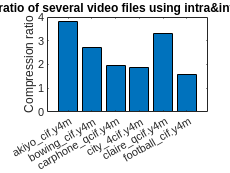

%lossless both

akiyo_frames = 300;
bowing_frames = 300;
carphone_frames = 382;
city_frames = 600;
claire_frames = 494;
football_frames = 260;

akiyo_original = 45621044;
bowing_original = 45621044;
carphone_original = 14524448;
city_original = 364957238;
claire_original = 18782912;
football_original = 39538238;

akiyo_both = 12038723;
bowing_both = 16785699;
carphone_both = 7392256;
city_both = 192872112;
claire_both = 5718371;
football_both = 24784968;

akiyo_time = [34.751  1.585];
bowing_time = [35.108 1.789];
carphone_time = [11.072  1.211];
city_time = [296.8770 17.193];
claire_time = [13.891  0.738];
football_time = [31.063  2.494];

X = categorical({'akiyo\_cif.y4m','bowing\_cif.y4m','carphone\_qcif.y4m','city\_4cif.y4m', 'claire\_qcif.y4m', 'football\_cif.y4m'});
Y2 = [(akiyo_original / akiyo_both) (bowing_original/bowing_both) (carphone_original/carphone_both) (city_original/city_both) (claire_original/claire_both) (football_original/football_both)];
bar(X, Y2);
title("Compression ratio of several video files using intra&inter frame encoding");
ylabel("Compression ratio");

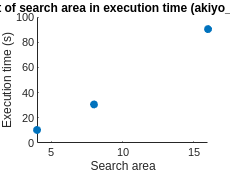


akiyo_TPF = akiyo_time ./ akiyo_frames;
bowing_TPF = bowing_time ./ bowing_frames;
carphone_TPF = carphone_time ./ carphone_frames;
city_TPF = city_time ./ city_frames;
claire_TPF = claire_time ./ claire_frames;
football_TPF = football_time ./ football_frames;

% bs = 16
akiyo_4 = 10.353; % 11557290
akiyo_8 = 30.599; % 11558999
akiyo_16 = 90.390; % 11559549

scatter([4 8 16], [akiyo_4 akiyo_8 akiyo_16], "filled");
title("Effect of search area in execution time (akiyo\_cif.y4m)");
xlabel("Search area");
ylabel("Execution time (s)");
ylim([0 100]);

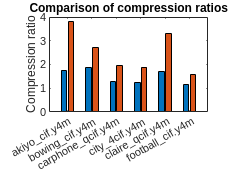


bar(X, [Y; Y2]');
title("Comparison of compression ratios");
ylabel("Compression ratio");

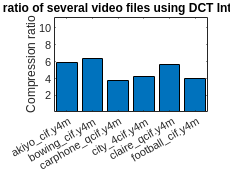

% dct
clear;
cla reset;

akiyo_frames = 300;
bowing_frames = 300;
carphone_frames = 382;
city_frames = 600;
claire_frames = 494;
football_frames = 260;

akiyo_original = 45621044;
bowing_original = 45621044;
carphone_original = 14524448;
city_original = 364957238;
claire_original = 18782912;
football_original = 39538238;

akiyo_dct = 7787565;
bowing_dct = 7216094;
carphone_dct = 3847704;
city_dct = 85549609;
claire_dct = 3331539;
football_dct = 9729891;

X = categorical({'akiyo\_cif.y4m','bowing\_cif.y4m','carphone\_qcif.y4m','city\_4cif.y4m', 'claire\_qcif.y4m', 'football\_cif.y4m'});
Y2 = [(akiyo_original / akiyo_dct) (bowing_original/bowing_dct) (carphone_original/carphone_dct) (city_original/city_dct) (claire_original/claire_dct) (football_original/football_dct)];
bar(X, Y2);
title("Compression ratio of several video files using DCT Intra-Frame encoding");
ylabel("Compression ratio");

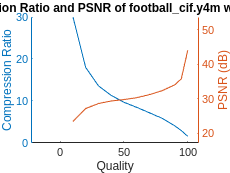


akiyo_time = [1.961  1.671];
bowing_time = [1.963  1.617];
carphone_time = [0.767  0.672];
city_time = [17.129  14.279];
claire_time = [0.890  0.736];
football_time = [1.916  1.928];

quality = [10 20 30 40 50 60 70 80 90 95 100];
psnr = [23.416443 27.179856 28.638831 29.364170 29.782949 30.329797 31.224276 32.358327 34.114346 35.838231 44.077635];
cr = [1319112 2198388 2909031 3491477 4075886  4657674 5501958 6738455 9729891 13417051 24810923];
cr = football_original ./ cr;
cla reset;
hold on;
yyaxis left;
plot(quality, cr);
title("Compression Ratio and PSNR of football\_cif.y4m with quality");
xlabel("Quality");
ylabel("Compression Ratio");
yyaxis right;
plot(quality, psnr);
ylabel("PSNR (dB)");
hold off;

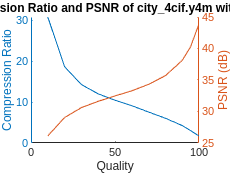


psnr = [26.129738 29.045188 30.617845 31.617957 32.472718 33.279736 34.314430 35.687696 38.108152 40.277673 43.917824];
cr = [11846744  19573509 25545226 30374665 34896370 40000111 48238166 60290477 85549609 120559943 213439699 ];
cr = city_original ./ cr;
cla reset;
hold on;
yyaxis left;
plot(quality, cr);
title("Compression Ratio and PSNR of city\_4cif.y4m with quality");
xlabel("Quality");
ylabel("Compression Ratio");
yyaxis right;
plot(quality, psnr);
ylabel("PSNR (dB)");
hold off;